# 某两帧eig匹配

close all;
addpath('./flann/');
addpath('./estimateRigidTransform')
s=1;
res=1;
% ModelCloud=clouds{1};
% DataCloud=clouds{2};
mo=114;
da=mo+3;


ModelCloud=pointCloud(trclouds{mo}.Location);%clouds{mo}clo1
DataCloud=pointCloud(trclouds{da}.Location);%clouds{da}
gridStep= 0.7;%30
overlap=0.8;
tic
[tarDesp,tarSeed,tarNorm] = extractEig(ModelCloud,gridStep);
[srcDesp,srcSeed,srcNorm] = extractEig(DataCloud,gridStep);
T = eigMatch(tarDesp,srcDesp,tarSeed,srcSeed,tarNorm,srcNorm,overlap,gridStep);
T = inv(T);

% T=modTf
R0= T(1:3,1:3);
t0= T(1:3,4);
Model= ModelCloud.Location(1:res:end,:)';
Data= DataCloud.Location(1:res:end,:)';
[MSE,R,t] = TrICP(Model, Data, R0, t0, 100, overlap);
MSE

MSE = single
2.6365e-04

% Motion=Rt2M(R0,t0);
Motion=Rt2M(R,t);
Motion(1:3,4)=Motion(1:3,4).*s;
toc

时间已过 0.824603 秒。


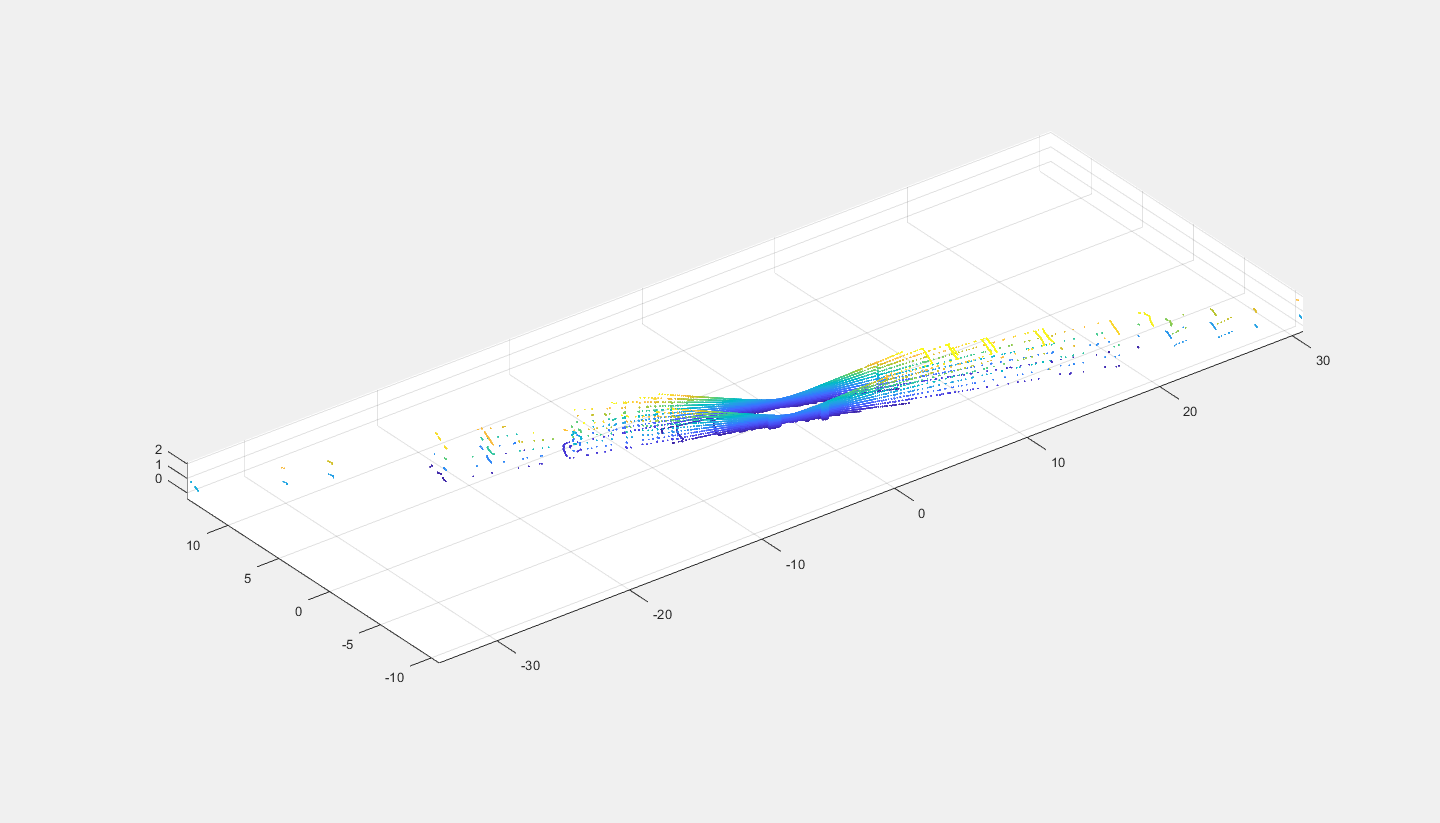

figure('position',[-1439 76 1440 823])
pcshow(pctransform(clouds{da},affine3d(Motion')));%clouds{da}
hold on;
pcshow(clouds{mo});

save good one

relativeMotion{da}=Motion;

relativeMotion{116}=eye(4)

relativeMotion = 1×150 cell 数组
    {4×4 double}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 

relativeMotion{115}=eye(4)

relativeMotion = 1×150 cell 数组
    {4×4 double}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 single}    {4×4 

clouds{116}=clouds{114}
clouds{115}=clouds{114}

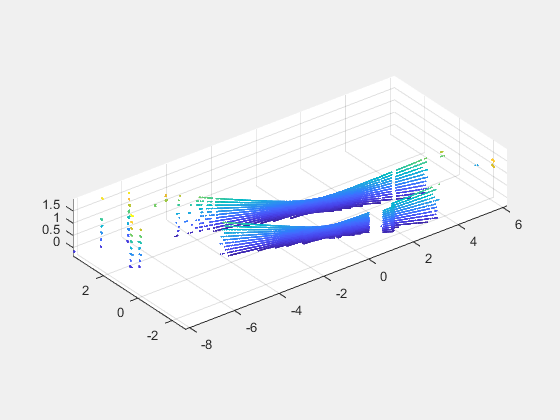

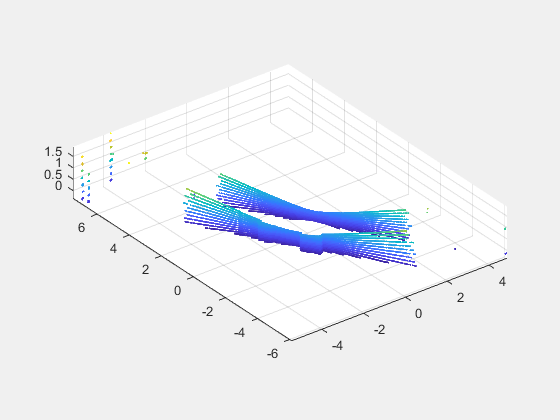

figure;
pcshow(trclouds{mo});
figure;
pcshow(trclouds{da});

figure;
pcshow(trclouds{1});
figure;
pcshow(trclouds{153});

微处理点云

Loca=clouds{mo}.Location;
sele=(Loca(:,2)<0.92)&(Loca(:,1)<-0.9);
clo1=pointCloud(Loca(sele,1:3));
Loca=clouds{da}.Location;
sele=(Loca(:,2)<0.93)&(Loca(:,1)<-2.1);
clo2=pointCloud(Loca(sele,1:3));


# 微调

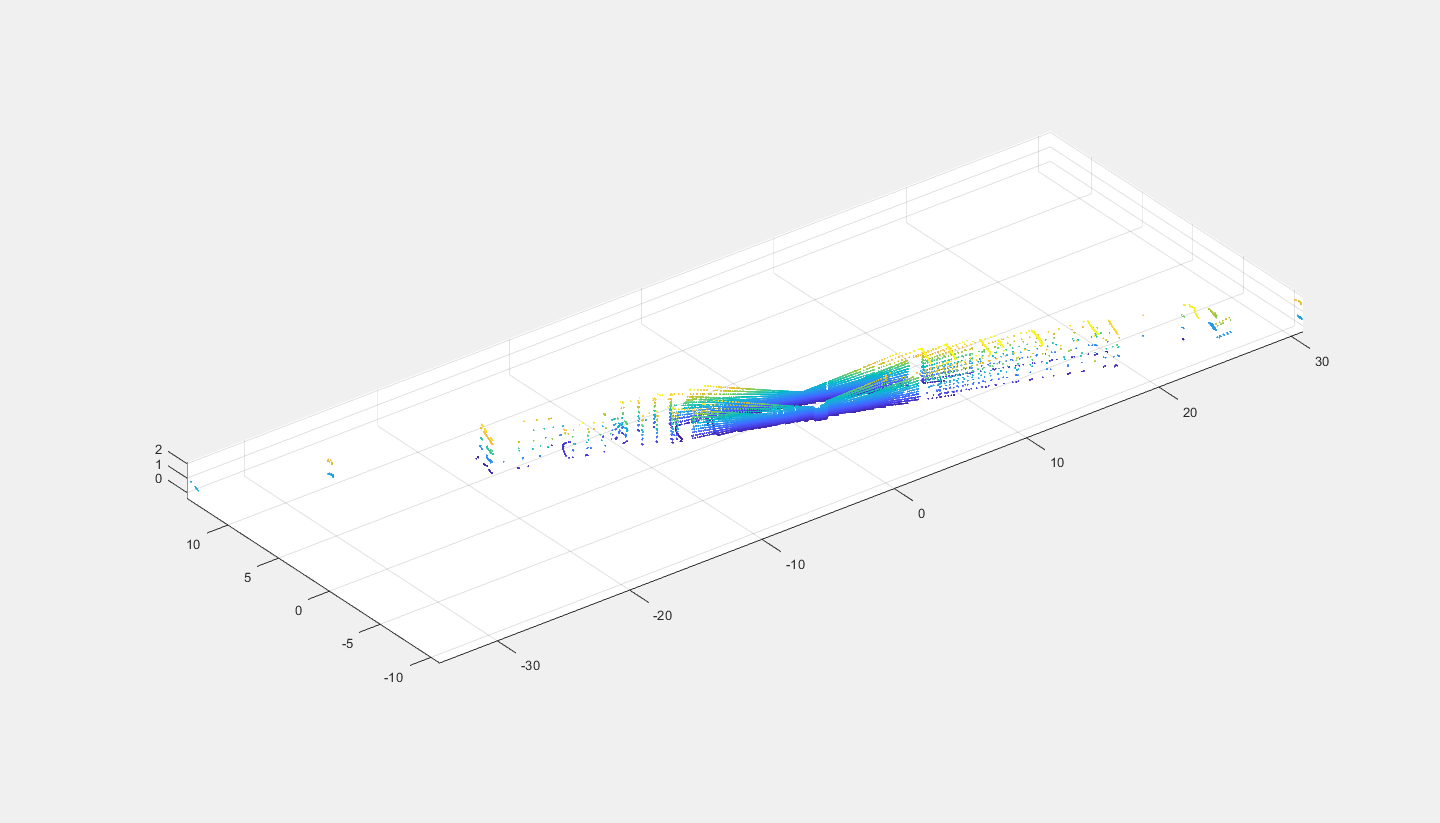

%加旋转
% tangle=tform2eul(Motion,'XYZ');
% tangle
% tangle(3)=tangle(3)-0.005;
% modTf=eul2tform(tangle,'XYZ');
% modTf(1:3,4)=Motion(1:3,4);

%加平移
% Motion= modTf;
modTf=Motion;
modTf(1:2,4)=modTf(1:2,4)-[addt]';

figure('position',[-1439 76 1440 823])
pcshow(pctransform(clouds{da},affine3d(modTf')));
hold on;
pcshow(clouds{mo});